# plot step response of the RC circuit transfer function

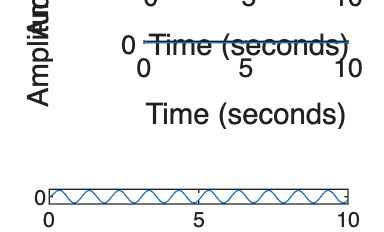

R=5;     %resistance
C=0.02;  %capacitance
tau=R*C;
t=0:0.01:10;

s=tf('s');

RC=1/(tau*s+1);

figure()
subplot(3,1,1)
step(RC,t)

subplot(3,1,2)
impulse(RC,t)

subplot(3,1,3)
u=sin(2*pi*t);
y=lsim(RC,u,t);
plot(t,y)

## plot root locus

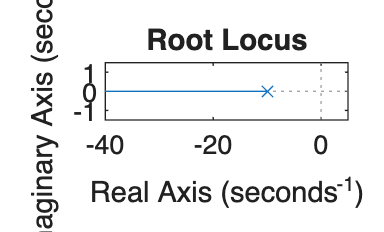

figure()
rlocus(RC)

## RLC circuit

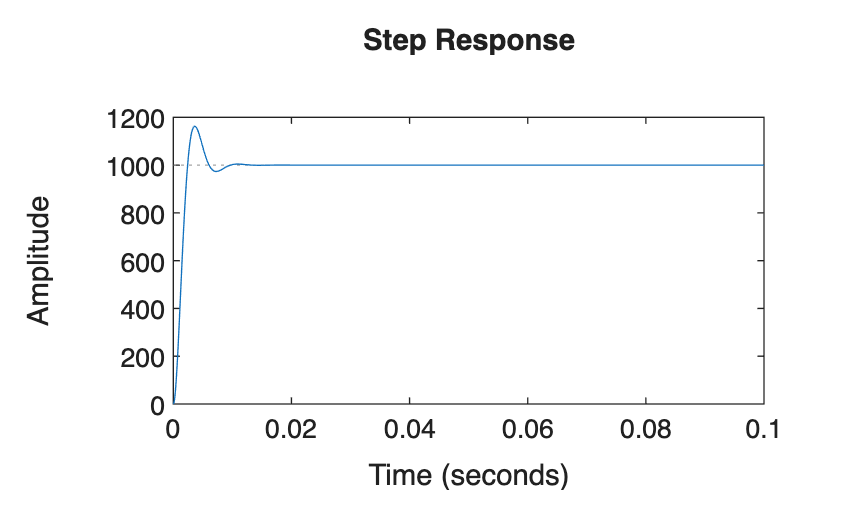


R=1;     %resistance
C=1000e-6;  %capacitance
L=1e-3;  %inductance
t=0:0.0001:0.1;

s=tf('s');

wn=1/sqrt(L*C);
zeta=(R/2)*sqrt(C/L);


RLC= (R/L)*(wn^2/(s^2+2*zeta*wn*s+wn^2));


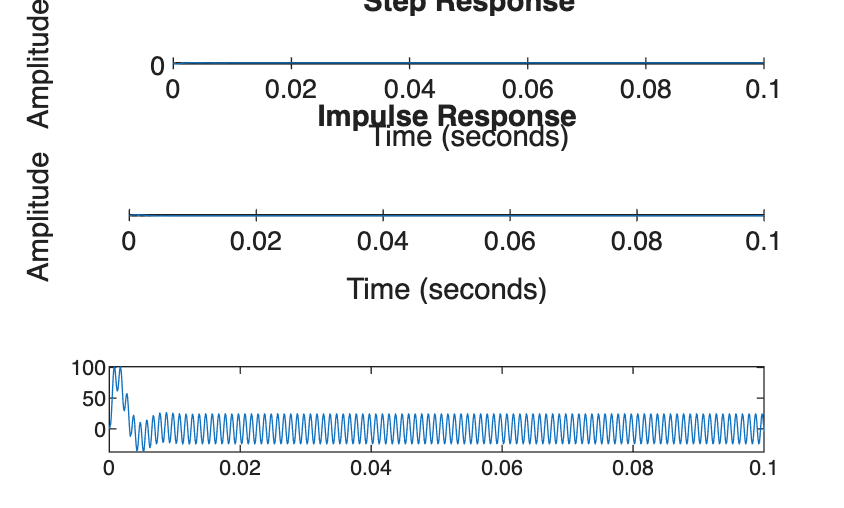

figure()
subplot(3,1,1)
step(RLC,t)

subplot(3,1,2)
impulse(RLC,t)

subplot(3,1,3)
u=sin(2*wn*pi*t);
y=lsim(RLC,u,t);
plot(t,y)